% %%load file
% %load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_21_01_51_55P2M_444118_220914_plane0_2023_05_04.08-47-27assemblysce6last/brainbow.mat')
% %load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_22_13_11_20P2M_444175_221125_plane0_2023_10_25.17-43-15assemblysce6last/brainbow.mat')
% % load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_24_16_42_06P2M_411582_230320_plane1_2023_04_05.17-57-09assemblysce6last/brainbow.mat')%,'Tr1b','WinActive','WinRest','Race')
% % num_recording = [1     2     7    15    18    22    23    24    29    34];%list_444118
% % num_recording = [3	25	30	35	36]; %list_444119
% % num_recording = [ 4	8	9	14	16	26	27	31	32]; %444152
% %num_recording = [5	10	12	13	17	19	37	38	39	40] ; %444175
% % num_recording = [6 33];  %411582
% % num_recording = [11 20] ; %443669
% % num_recording = [21 28];  %444112
% num_recording =[6 11 21 2 18 1 23 34 3 25 8 26 4 9 5 10 12 17 13]; %all but only one time
% % clear
% % close all
% % num_recording =[6 11 21 2 18 1 23  3 25 8 26 4 9 5 10 12 17 13]; %all but only one time
% load('/Users/platel/Desktop/exp/brainbow hippocampus/best/best.mat')
% % load('/Users/platel/Desktop/exp/brainbow hippocampus/bestcue/bestcue.mat')
% % newlist=matfile;
% PathSave= '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/nocue-rastermap/';
% % for file_num=1:numel(newlist)
% % for file_num=num_recording
% file_num=6;
% filename=cell2mat(newlist(file_num));
% load (filename,'assembly','F','speed','iscell','NCell','NClOK','Nz','colorcell','CellClraw','color_assembly','spks','WinActive')
% %load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_24_16_42_06P2M_411582_230320_plane1_2023_04_05.17-57-09assemblysce6last/brainbow.mat')%,'Tr1b','WinActive','WinRest','Race')
% 
% [path,name,ext] = fileparts(filename);
% [path,name,ext] = fileparts(path);


%preprocessing signal
METHODE=1;%'rastermap'
% METHODE=2%'correlation'
DF=double(spks(iscell(:,1)>0,:));
% DF=double(F(iscell(:,1)>0,:));
% ws = warning('off','all');
% for i=1:NCell
%     p0=polyfit(1:Nz,DF(i,:),3);
%     DF(i,:)=DF(i,:)./polyval(p0,1:Nz);
% end
% warning(ws)%% preprocessing
DF = sgolayfilt(DF',3,7)';%was at 5
% DF=DF./median(DF,2);
DF(DF<50)=0;
% 
% % DF=normalize(DF,2,"zscore");
% DF=normalize(DF,2,"center","median","scale","mad");
% DF(DF<0)=0;
% % DF=normalize(DF,2,"center","mean","scale","std");
% Fcenter=normalize(DF,2,"center","mean");

DFsmooth=double(spks(iscell(:,1)>0,:));
DFsmooth = sgolayfilt(DFsmooth',3,7)';
DFsmooth=DFsmooth./median(DFsmooth,2);
DFsmooth=smoothdata(DFsmooth,2,"gaussian",100);


%%binarization speed

smoothed_speed=smoothdata(speed,2,"gaussian",100);

Unrecognized function or variable 'speed'.

threshold = 2; % Définir le seuil
binary_speed = double(smoothed_speed > threshold); % Binariser la série temporelle
% 
% figure
% plot(speed);
% hold on;
% plot(binary_speed * max(smoothed_speed), 'r'); 
% hold off

% Calculer les points de changement dans le signal
change_points = diff([0; binary_speed(:); 0]); % Ajoutez des zéros au début et à la fin pour détecter les changements aux extrémités

% Trouver les indices de début (où le signal passe de 0 à 1)
start_indices = find(change_points == 1) - 1; % Soustrayez 1 pour corriger l'indice après 'diff'

% Trouver les indices de fin (où le signal passe de 1 à 0)
end_indices = find(change_points == -1) - 1; % Soustrayez 1 pour corriger l'indice après 'diff'

% Exclure le premier élément si celui-ci est zéro
start_indices(start_indices == 0) = [];

% Vérifier si le premier événement de fin a un début correspondant
if isempty(start_indices) || start_indices(1) > end_indices(1)
    end_indices(1) = []; % Supprimer le premier indice de fin s'il n'a pas de début correspondant
end

% Assurez-vous que les indices sont valides et qu'ils ne dépassent pas la longueur de 'binary_signal'
start_indices = start_indices(start_indices > 0 & start_indices <= length(binary_speed)-200);
end_indices = end_indices(end_indices > 0 & end_indices <= length(binary_speed));

% Visualisation
% figure; % Créer une nouvelle figure
% plot(binary_speed, 'LineWidth', 2);
% hold on;
% scatter(start_indices, binary_speed(start_indices), 'g', 'filled'); % Marquer les débuts en vert
% scatter(end_indices, binary_speed(end_indices), 'r', 'filled'); % Marquer les fins en rouge
% xlabel('Temps');
% ylabel('Signal Binaire');
% title('Début et Fin des Événements Binaires');
% hold off

METHODE=1;
if METHODE==1
    ops.nC = 20;%, number of clusters to use 
    ops.iPC = 1:100;%, number of PCs to use 
    ops.isort = [];%, initial sorting, otherwise will be the top PC sort
    ops.useGPU = 0;%, whether to use the GPU
    ops.upsamp = 100;%, upsampling factor for the embedding position
    ops.sigUp = 1;%, % standard deviation for upsampling
    % [isort1, isort2, Sm] = mapTmap(DF(:,WinActive),ops);
    [idx2, isort2, Sm] = mapTmap(DF,ops);
    
    % DF=Tr1b(isort1,:);
end

Elapsed time is 0.199316 seconds.
Elapsed time is 0.318685 seconds.


if METHODE==2%'correlation'
max_lag = 200;
sm_speed=smoothdata(speed,2,"gaussian",100);
sm_DF=smoothdata(DF,2,"gaussian",10);
max_corr_values = zeros(1,NCell);
lags_at_max_corr = zeros(1, NCell);
% diff_speed=vertcat(diff(speed), 0);
% diff_speed(diff_speed<0)=0;
tic
for i = 1:NCell
        % Calculate cross-correlation
        [cross_corr, lags] = xcorr(speed, DF(i, :), max_lag,"coeff");
        % [cross_corr, lags] = xcorr(diff_speed, DF(i, :), max_lag,"coeff");           
        % Find maximum correlation and corresponding lag
        [max_corr, idx_max_corr] = max(cross_corr);
        lags_at_max_corr(i) = lags(idx_max_corr);
        max_corr_values(i) = max_corr;
end

% signi_cells=find(max_corr_values>graythresh(max_corr_values));
% lags_at_max_corr=lags_at_max_corr(signi_cells)
[idx1, idx2 ]=sort(lags_at_max_corr,2,'descend');
end

Unrecognized function or variable 'METHODE'.

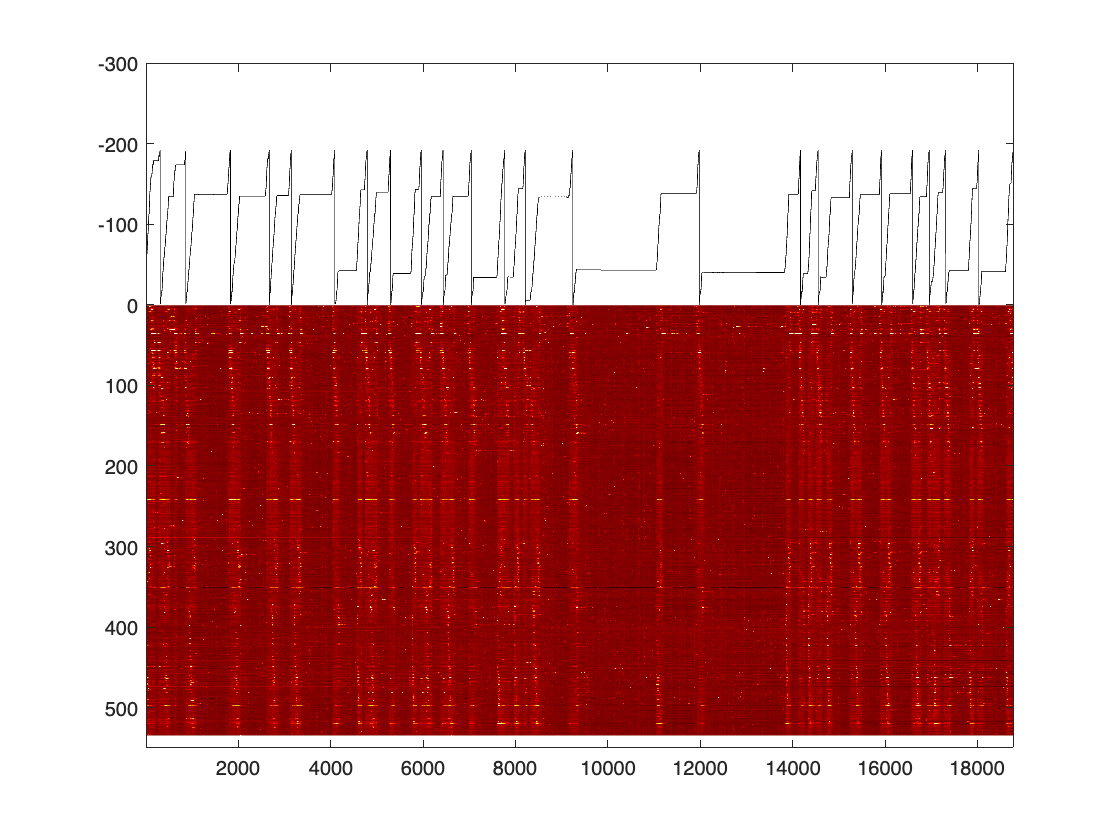

figure
% imagesc(DFsmooth(idx2,:))
imagesc(DF(idx2,:))
colormap ("hot")
caxis ([0 5])
hold on
% plot (-speed*10,'Color','k')
plot (-position,'Color','k')
% ylim([-300 NCell]) 
ylim([-300 550]) 
hold off
refresh


if METHODE==2
 figure;plot(-lags_at_max_corr(idx2),1:NCell,'LineWidth',2,'Color','k')
 box off
xline(0,'Color','b','LineWidth',2)
axis ij
end


%for place cells 
DF=DF()


NCell=size(F,1);
for ncell=1:NCell
    for n=1:192
        list=find (position<n & position >n-1);
        Fluo(ncell,n)=mean(DF(ncell,list'));
    end
end

j=0

j = 0

for i=list'
    j=j+1;
    test(j)=DF(1,i);
end

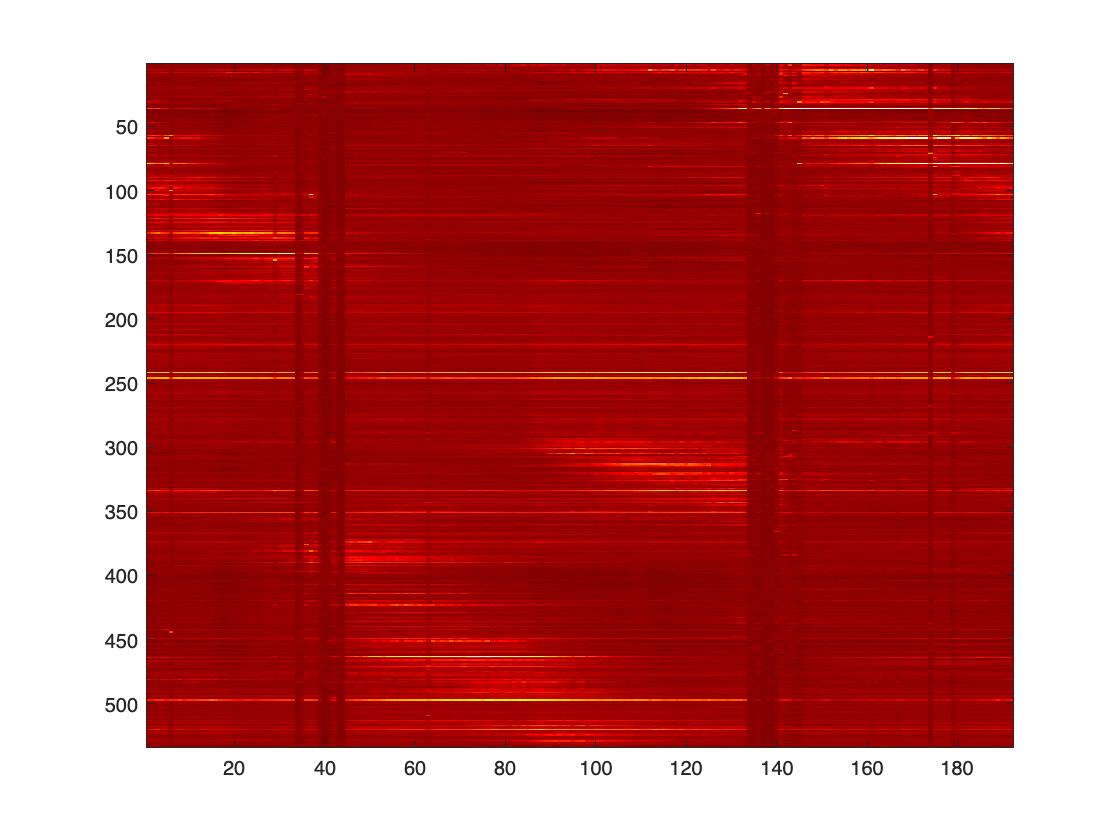


imagesc(Fluo(idx2,:))
colormap ("hot")
caxis ([0 5])

%%Peri Mouvement Time Histogram
%idx2=isort1;
window=100;
PSTH=[];
DFtest=double(spks(iscell(:,1)>0,:));
DFtest = sgolayfilt(DFtest',3,7)';
DFtest=DFtest./median(DFtest,2);

for n=1:numel(start_indices)
    start=start_indices(n);
    PSTH(:,:,n)=DFtest(:,start-100:start+200);
end
mean_PSTH=mean(PSTH,3);
% sm_mean_PSTH=smoothdata(mean_PSTH,2,"gaussian",10);
% sm_mean_PSTH=smoothdata(sm_mean_PSTH,1,"gaussian",2);
figure
% imagesc(sm_mean_PSTH(idx2,:))

imagesc(mean_PSTH(idx2,:))
% imagesc(PSTH(isort1,:,1))
colormap ("hot")
caxismin=1;
caxismax=6;
caxis ([caxismin caxismax])
xline(100,'Color','w','LineWidth',2)
set(gcf, 'Position', [10 10 500 400]);
set(gca,'XTickLabel',{'-5','0','5','10', '15','20'},'FontSize', 20);
title('PMTH','FontSize',20)
xlabel('time(s)','FontSize',20)

%plot color of cells on sorted raster
figure
imagesc(DFsmooth(idx2,:))

colormap ("hot")
caxis ([0 10])
i=0;
for n=1:NCell

    % if colorcell(idx2(n))==8
    %     col='w';
    if colorcell(idx2(n))==1
        col='red';
    elseif colorcell(idx2(n))==2 
        col='green';
    elseif colorcell(idx2(n))==3 
        col='blue';
    elseif colorcell(idx2(n))==4 
        col='yellow';
        % col='white';
    elseif colorcell(idx2(n))==5 
        col='magenta';
    elseif colorcell(idx2(n))==6 
        col='cyan';
    elseif colorcell(idx2(n))==7 
        col='black';
    elseif colorcell(idx2(n))==8 
        col='black';
    % else
    %     col='black';
    end
        % yline(isort1(n),'LineWidth',1,'Color',col)
        line([-1000 0], [idx2(n) idx2(n)], 'LineWidth', 1 , 'Color', col);
        i=i+1;
end
xlim([-1000 Nz]) 
% namegraph=strcat(['rastermap_run assembly' num2str(ass), '.png']);
% exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')


%plot assembly over sorted raster

for ass=1:numel(assembly)
    %figure('visible','off');
    figure
    % Ftemp=smoothdata(DF,2,"gaussian",100);
    imagesc(DFsmooth(idx2,:))
    colormap ("hot")
    title (['Assembly' num2str(ass)])
    caxis ([0 10])
    i=0;
    for n=cell2mat(assembly(ass))
        y=find (n==idx2);

    if colorcell(n)==1
        col='red';
    elseif colorcell(n)==2 
        col='green';
    elseif colorcell(n)==3 
        col='blue';
    elseif colorcell(n)==4 
        col='yellow';
    elseif colorcell(n)==5 
        col='magenta';
    elseif colorcell(n)==6 
        col='cyan';
    elseif colorcell(n)==7 
        col='white';
    elseif colorcell(n)==8 
        col='white';

    end
        yline(y,'LineWidth',1,'Color',col)
        % i=i+1;
        % yline(y,'LineWidth',1,'Color',colors(ass,:))
        % if y>200
        %     i=i+1;
        % end


    end
        % i/numel(cell2mat(assembly(ass)))*100
    % namegraph=strcat(['rastermap_run assembly' num2str(ass), '.png']);
    % exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')
end


% distance intra-assemblée

for ass=1:numel(assembly)
    isort1_ass=[];
    for n=cell2mat(assembly(ass))

        % y=find (n==isort1);
        y=find (n==idx2);
        isort1_ass=[isort1_ass  y];
        
    end
    pairwise_distance=pdist(isort1_ass');
    mean_pairwise_distance_ass(ass)=mean(pairwise_distance)/NCell;
    % figure
    % histogram(pairwise_distance)
    % title (['assembly ' num2str(ass)])

end
mean_pairwise_distance_ass;
figure
bar(mean_pairwise_distance_ass)
ylim([0 1])
box off
title('distance intra-assembly','FontSize',20)
set(gca,'FontSize', 20);
% xlabel('FontSize',20)


% shuffling pour calcul distance cellules prise au hasard / nb cellule meme
% assemblée
maxshuffle=1000;
mean_pairwise_distance_ass_sh=zeros(numel(assembly)  ,maxshuffle);
for ass=1:numel(assembly)   % on scanne les assemblées 
    
    numcell=length(cell2mat(assembly(ass)));

    for nshuffle=1:maxshuffle
        list_sh=randperm(NCell);
        list_sh=list_sh(1:numcell);

        pairwise_distance=pdist(list_sh');
        mean_pairwise_distance_ass_sh(ass,nshuffle)=mean(pairwise_distance)/NCell;
    end
    mean_mean_pairwise_distance_ass_sh(ass)=mean(mean_pairwise_distance_ass_sh(ass,:),2);
    % figure
    % histogram(pairwise_distance,30)
    % title (['color ' num2str(col)])
end

for ass=1:numel(assembly)
    % figure
    % histogram(mean_pairwise_distance_ass_sh(ass,:),30,'Normalization','percentage')
    % xlim ([0.2 0.4])
    % hold on 
    % histogram(mean_pairwise_distance_ass(ass),500,'Normalization','percentage')
    % hold off
    % title (['assemblée ' num2str(ass)]) 
    % % mean_pairwise_distance_col(col)
    % % prctile(mean_pairwise_distance_col_sh(col,:),5)
    
    if mean_pairwise_distance_ass(ass)<prctile(mean_pairwise_distance_ass_sh(ass,:),5)
        disp('significantly closer')
    else
        disp('not significant')
    end
end
%mean_pairwise_distance
%calculer % assemblée en séquence, dans correlé et dans inhibé

% distance cellules meme couleur / tri 

for col=1:6   % on scanne les couleurs 
    
    list_cell=[];
    numcell=find (colorcell==col);

    for n=1:numel(numcell)
        y=find(idx2 == numcell(n));
        list_cell=[list_cell  y];
    end
    % end

    pairwise_distance=pdist(list_cell');
    mean_pairwise_distance_col(col)=mean(pairwise_distance)/NCell;
    % figure
    % histogram(pairwise_distance,30)
    % title (['color ' num2str(col)])
end
        
%         pairwise_distance=pdist(DF(colorcell==n,:)');
%         % y=find (n==isort1);
%         y=find (n==idx2);
%         isort1_ass=[isort1_ass  y];
% 
%     pairwise_distance=pdist(isort1_ass');
    % mean_pairwise_distance(ass)=mean(pairwise_distance)/NCell;

% 
% %end
% mean_pairwise_distance_col;
figure;
bar(mean_pairwise_distance_col)
ylim([0 1])
box off
title('distance cellules memes couleurs','FontSize',20)
set(gca,'FontSize', 20);


% shuffling pour calcul distance cellules prise au hasard / nb cellule meme
% couleur
maxshuffle=1000;
mean_pairwise_distance_col_sh=zeros(6,maxshuffle);
for col=1:6   % on scanne les couleurs 
    
    list_cell=[];
    nbcell=numel(find (colorcell==col));

    for nshuffle=1:maxshuffle
        list_sh=randperm(NCell);
        list_sh=list_sh(1:nbcell);

        pairwise_distance=pdist(list_sh');
        mean_pairwise_distance_col_sh(col,nshuffle)=mean(pairwise_distance)/NCell;
    end
    mean_mean_pairwise_distance_col_sh(col)=mean(mean_pairwise_distance_col_sh(col,:),2);
    % figure
    % histogram(pairwise_distance,30)
    % title (['color ' num2str(col)])
end

for col=1:6
    % figure
    % histogram(mean_pairwise_distance_col_sh(col,:),30,'Normalization','percentage')
    % xlim ([0.2 0.4])
    % hold on 
    % histogram(mean_pairwise_distance_col(col),500,'Normalization','percentage')
    % hold off
    % title (['couleur ' num2str(col)]) 
    % % mean_pairwise_distance_col(col)
    % prctile(mean_pairwise_distance_col_sh(col,:),5)
    disp (['couleur' num2str(col)])
    if mean_pairwise_distance_col(col)<prctile(mean_pairwise_distance_col_sh(col,:),10)
        disp('significantly closer')
    else
        disp('not significant')
    end
end
% figure;
% bar(mean_pairwise_distance_col)
% ylim([0 1])
% box off
% title('distance cellules memes couleurs','FontSize',20)
% set(gca,'FontSize', 20);
return

%overlap with assembly
for n=1:numel (assembly)
        intersection{n}=intersect(isort1(1:440),cell2mat(assembly(n)));
        inter(n)=numel(intersection{n})/numel(cell2mat(assembly(n)));
end
figure
for n=1:numel (assembly)
    
    bar (inter)
    % hold on
    % title(['intersection cluster ortho' num2str(n)])
end
% hold off



 
ops.nC = 20;%, number of clusters to use 
ops.iPC = 1:100;%, number of PCs to use 
ops.isort = [];%, initial sorting, otherwise will be the top PC sort
ops.useGPU = 0;%, whether to use the GPU
ops.upsamp = 100;%, upsampling factor for the embedding position
ops.sigUp = 1;%, % standard deviation for upsampling
% [isort1, isort2, Sm] = mapTmap(DF(:,WinActive),ops);
[isort1, isort2, Sm] = mapTmap(DF,ops);

% DF=Tr1b(isort1,:);



%representation with cumulative distance
sampling_rate=10;
deltaTime = 1/sampling_rate; % Time interval between measurements, adjust as necessary

% Convert speed to distance for each interval
distanceMatrix = speed * deltaTime; % If deltaTime is 1, this line can be omitted

% Calculate cumulative distance
cumulativeDistance = cumsum(distanceMatrix, 1); % Assuming time is along the second dimension (columns)
epsilon = 1e-6; % Small value to adjust duplicates
for i = 2:length(cumulativeDistance)
    while ismember(cumulativeDistance(i), cumulativeDistance(1:i-1))
        cumulativeDistance(i) = cumulativeDistance(i) + epsilon;
    end
end
% Desired distances for interpolation
desiredDistances = linspace(min(cumulativeDistance(:)), max(cumulativeDistance(:)), Nz);

% Interpolating neuronal activity to these distances
% Assuming neuronal activity is sampled in such a way that each column corresponds to the measurements in cumulativeDistance
% interpolatedActivity = interp1(desiredDistances, Tr1b(1,:),'linear');
for cellIdx = 1:size(Tr1b, 1)
    % interpolatedActivity(cellIdx, :) = interp1(cumulativeDistance, Tr1b(cellIdx, :), desiredDistances, 'linear');
    interpolatedActivity(cellIdx, :) = interp1(cumulativeDistance, Tr1b(cellIdx, :), desiredDistances, 'linear');

end

% Now you can plot, here's an example of plotting the activity of the first cell
% figure
% plot(desiredDistances, interpolatedActivity(1, :));
% xlabel('Cumulative Distance');
% ylabel('Neuronal Activity');
%resample interpolatedActivity
[P, Q] = rat(max(desiredDistances)/Nz); % Compute rational approximation for the resampling factor
resamp_interpolatedActivity = resample(interpolatedActivity', P, Q)';

% Ftemp=smoothdata(resamp_interpolatedActivity,2,"gaussian",100);
% % Ftemp=smoothdata(Ftemp,1,"gaussian",10);
% imagesc(Ftemp(isort1,:))
% colormap ("hot")
% hold on
% % plot (-cumulativeDistance/10)
% % plot(-interpolatedActivity(124, :)*100-10);
% % plot(-interpolatedActivity(427, :)*100-110);
% hold off
% % plot (-binary_signal*20)
% % hold off
% 
% caxis ([0 10])
% ylim([0 NCell]) 
% namegraph=strcat(['distance' , name, '.png']);
% % exportgraphics(gcf,[PathSave namegraph],'Resolution',300)
%end
return